load('UnitaryFakeProfile_T0_1_many.mat');
%load('UnitaryFakeProfile.mat');
%Load the Library with all functions
addpath('../Library')
%Define the physical constant
mli=9.988346*10^-27;  %kg
hbar=1.0545718*10^(-34); %SI
hh=2*pi*hbar;%SI Planck constant
omega=23.9*2*pi; %in rad/s
pixellength=1.44*10^-6; %in m
sigma0=0.215*10^-12/2; %in m^2
warning('off','all');
[ KappaTildeT_U, PTildeT_U, TTildeT_U, ~, ~] = VirialUnitarity( );

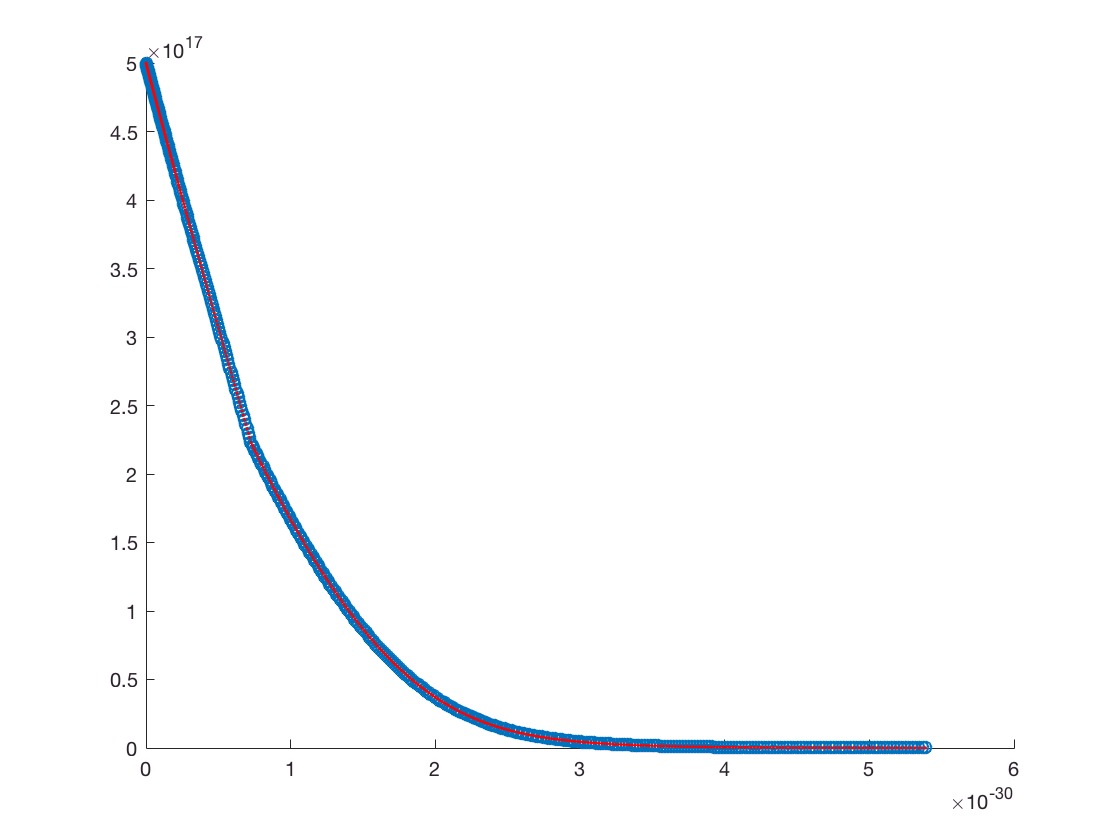

n=bin_n_vec_TTilde/2;
z=bin_z_TTilde_vec;
%scatter(z,n);
V=0.5*mli*omega^2*z.^2;
[Vsort,B]=sort(V);
nsort=n(B);
scatter(V,n);
hold on
scatter(Vsort,nsort,'r.');
hold off

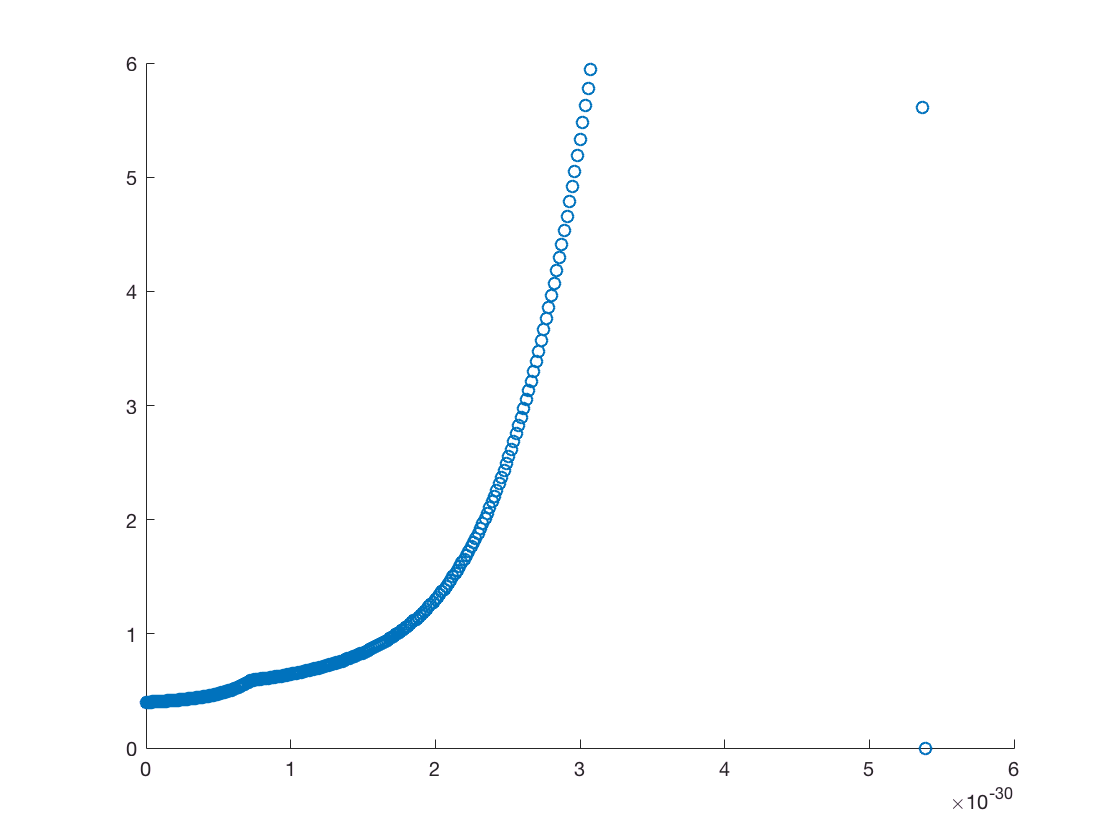

[~,~,Pt]=GetPvsV( nsort,Vsort);
Kt=GetKappavsVFiniteD( nsort,Vsort,4);
scatter(Vsort,Pt);
ylim([0,6]);

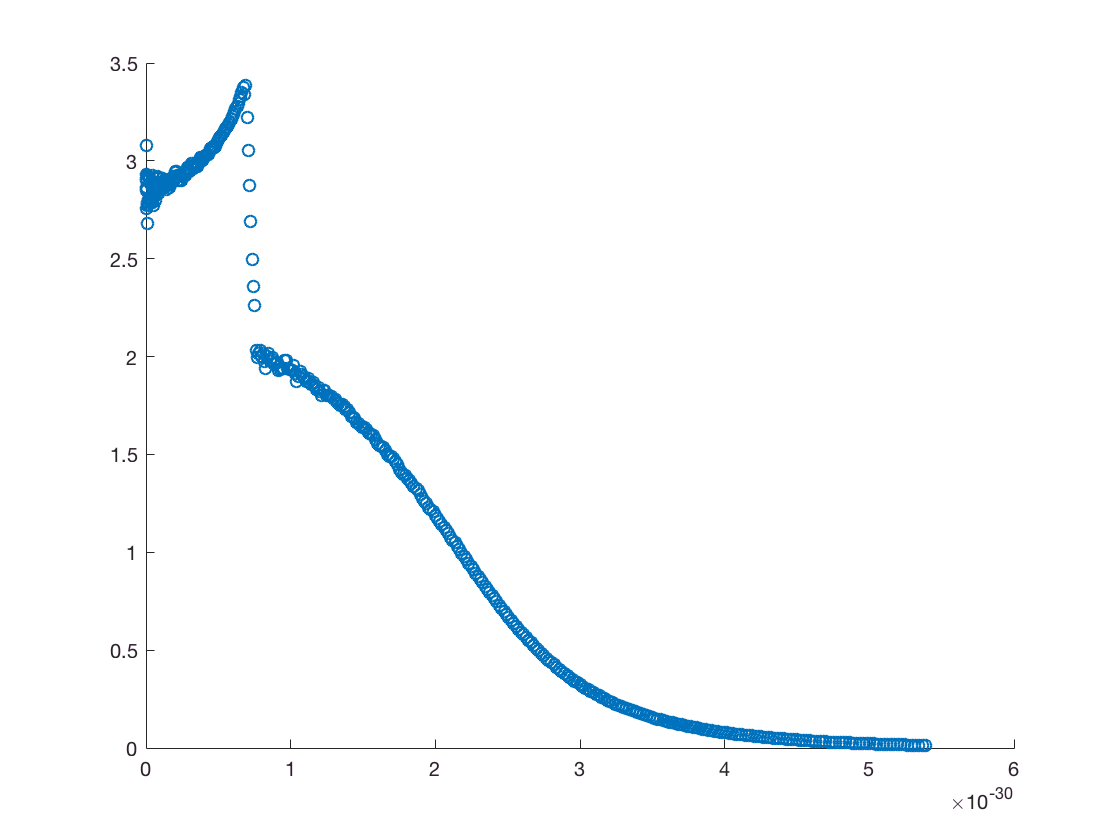

scatter(Vsort,Kt)

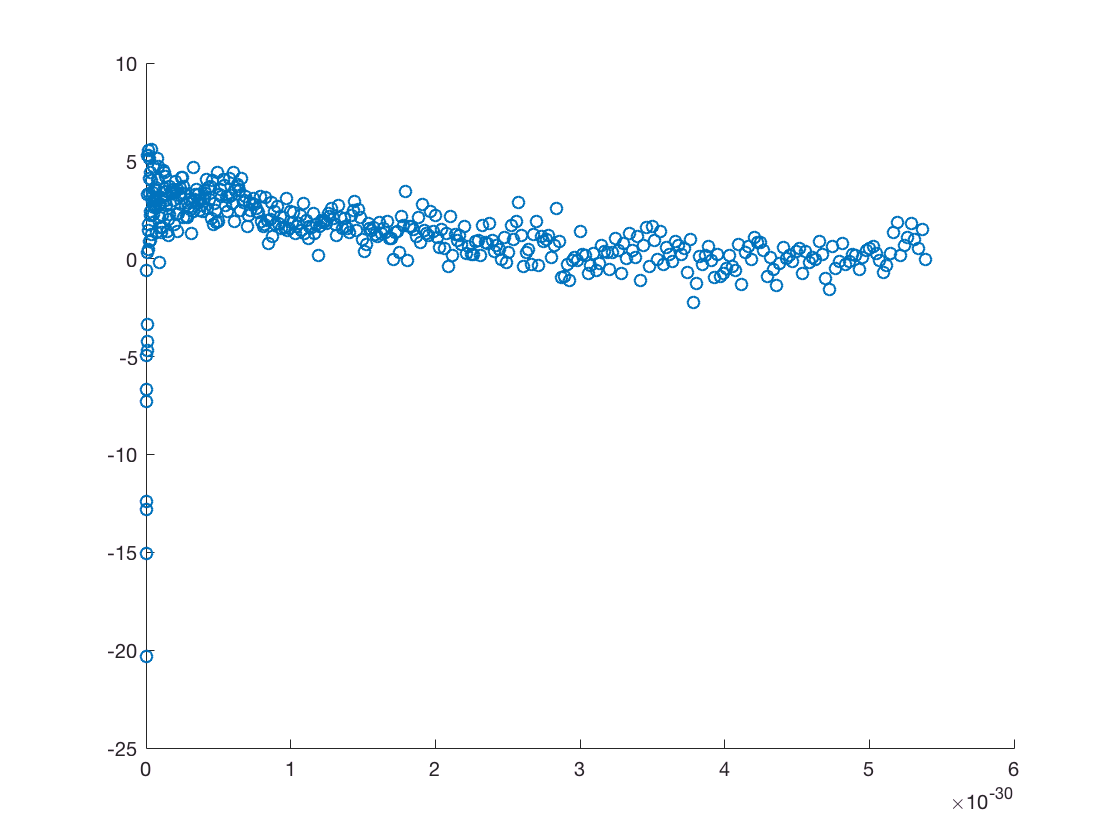

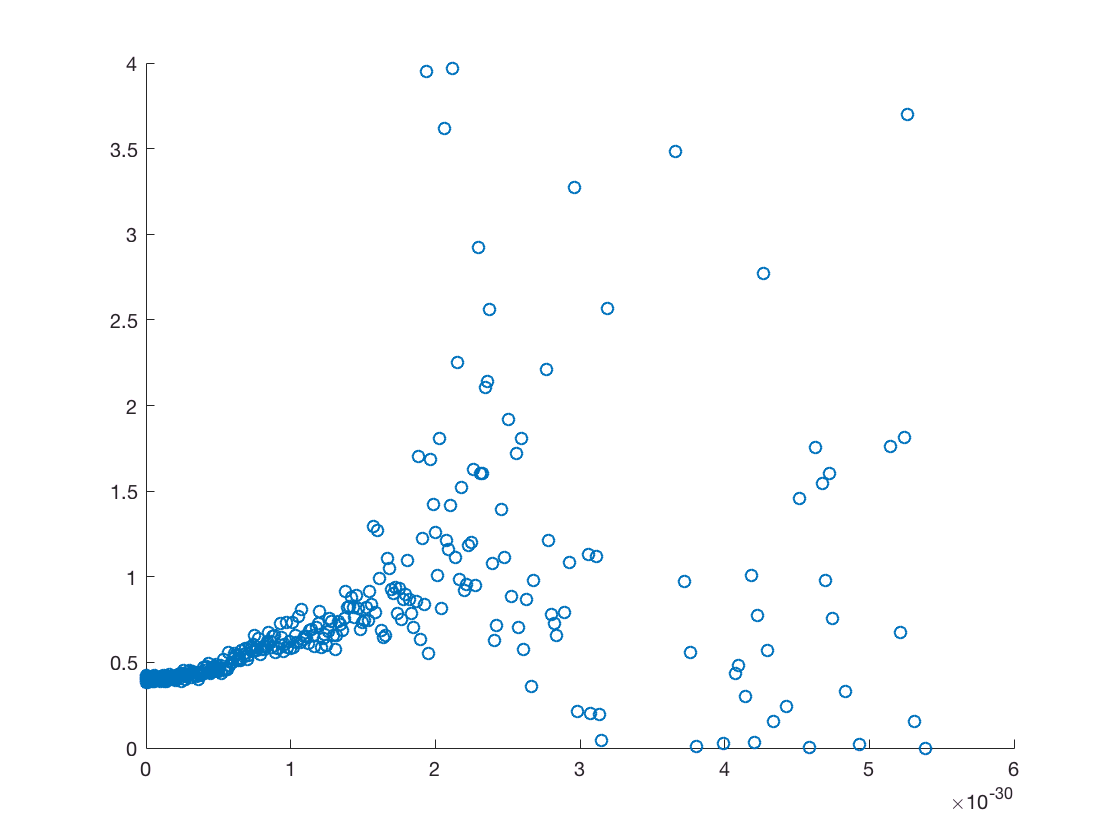

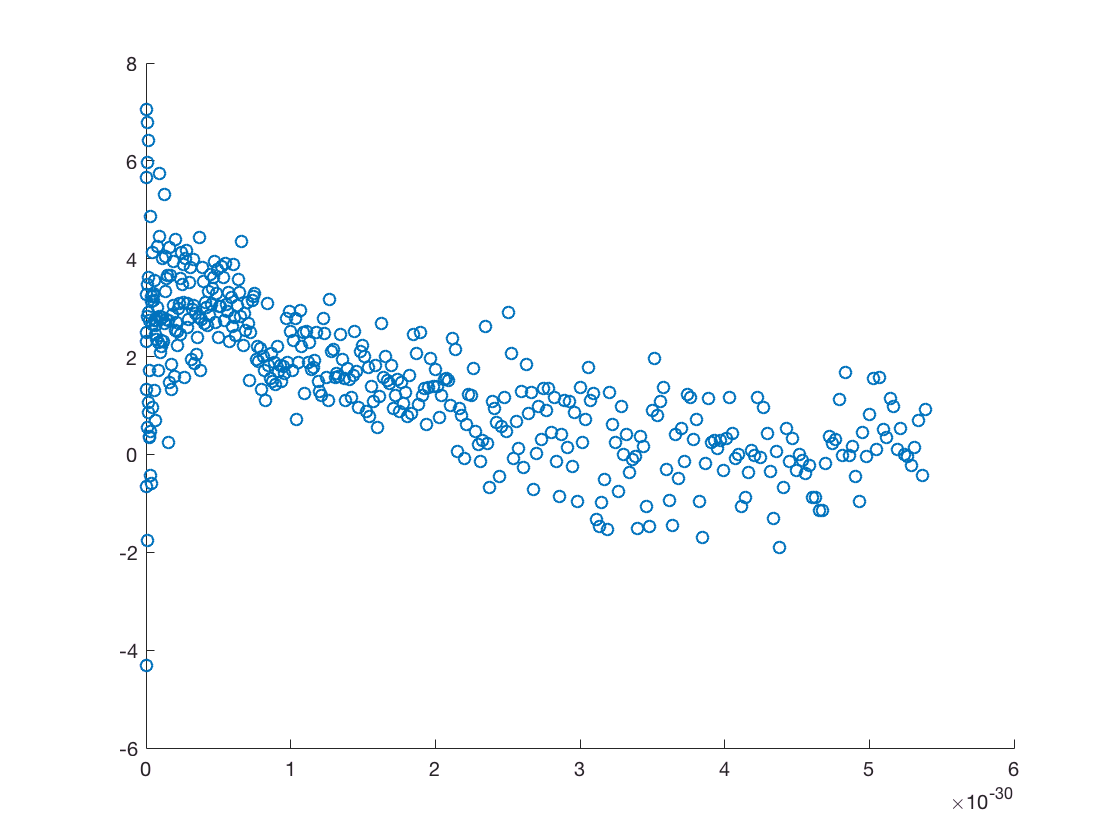

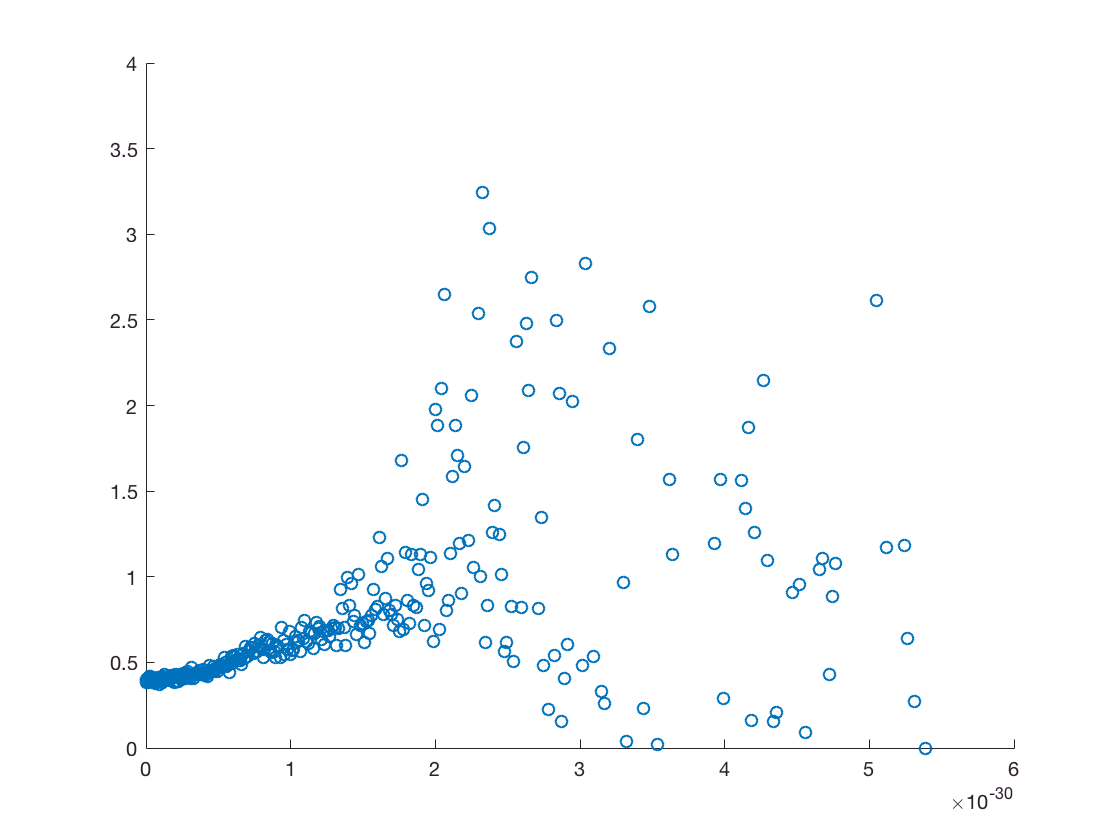

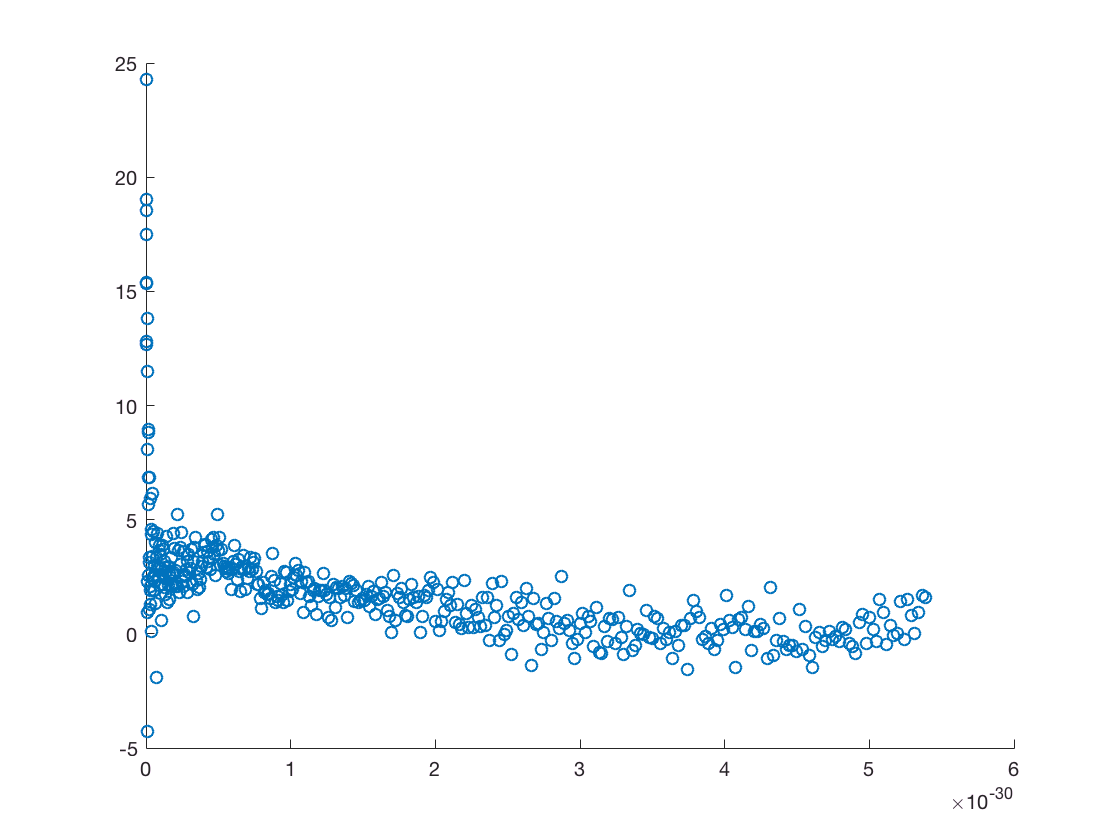

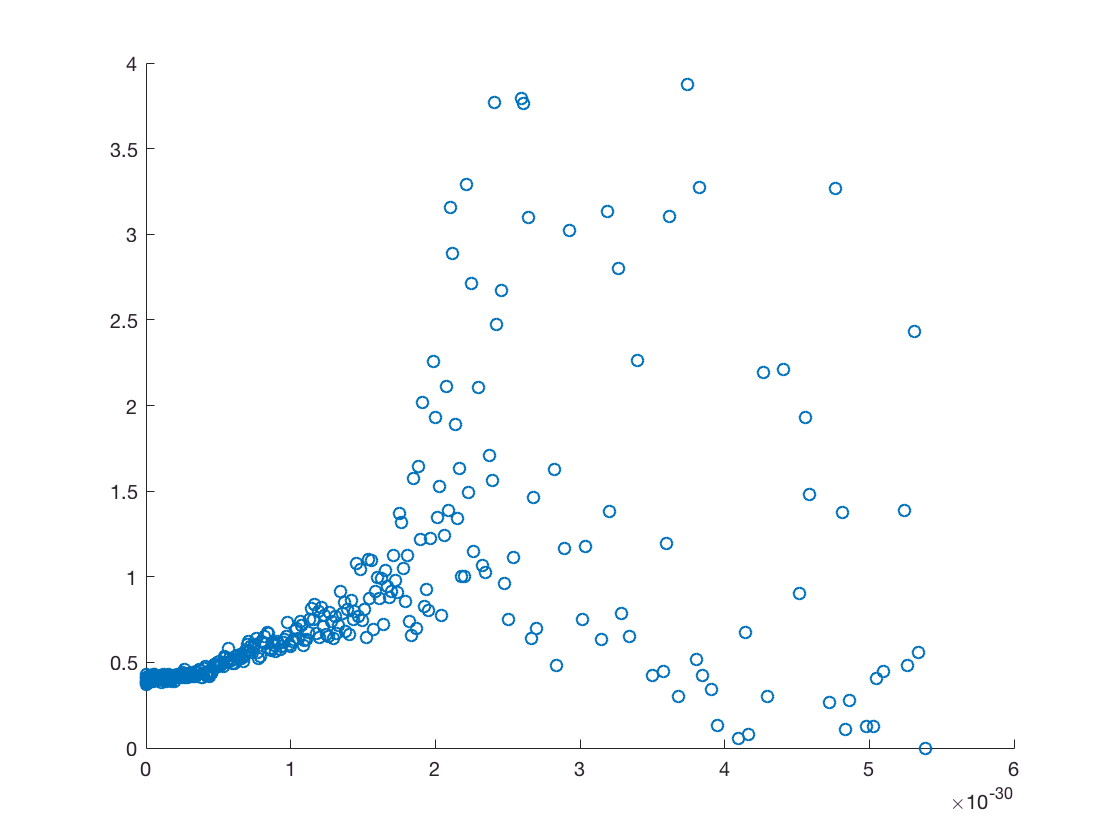

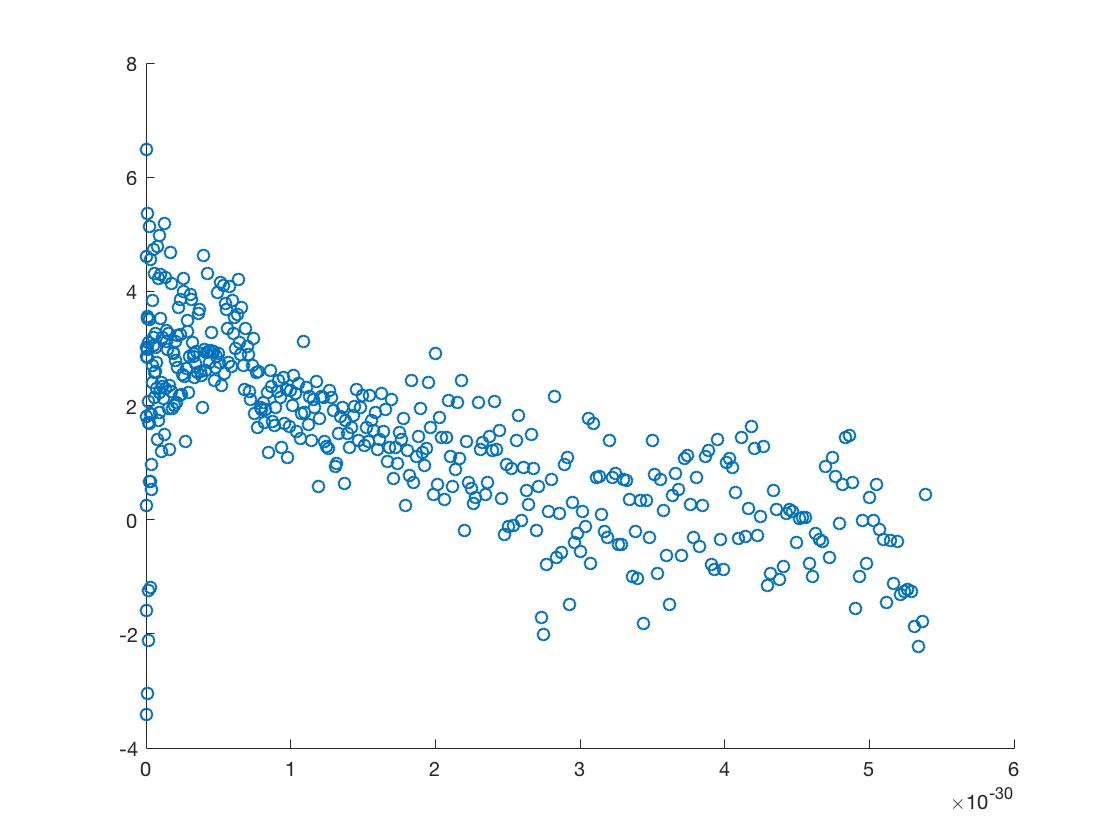

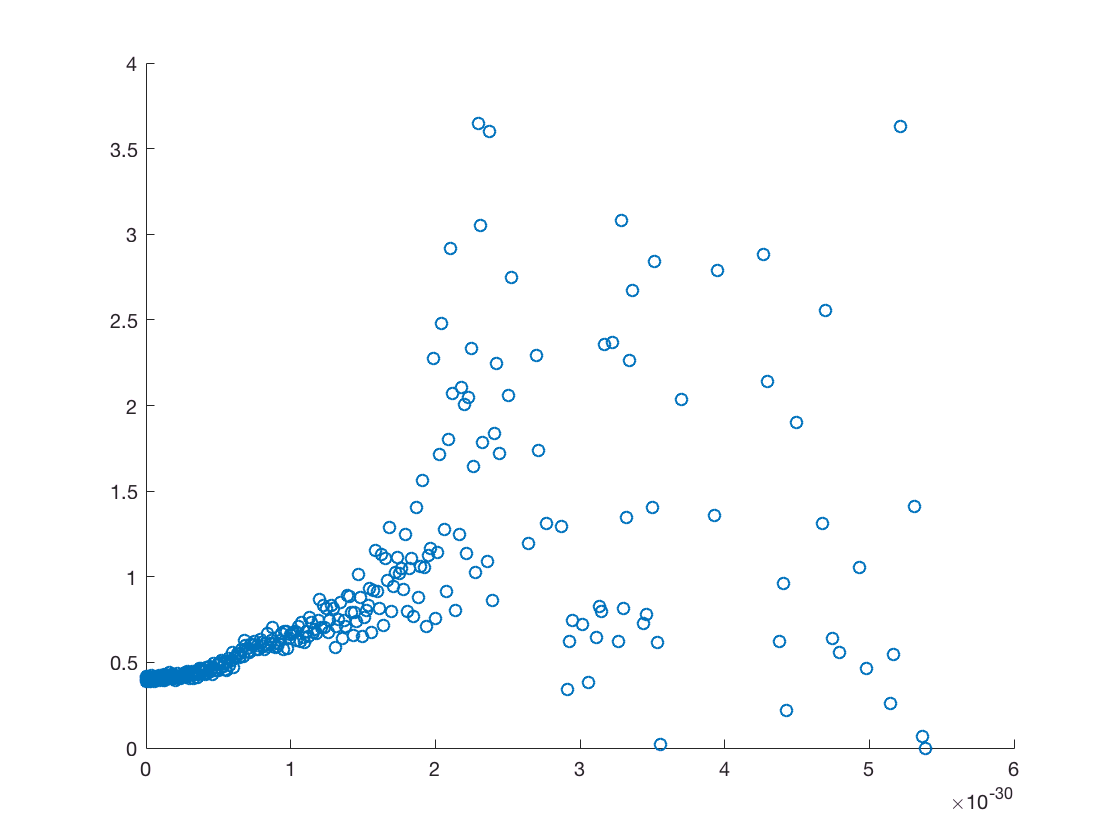

N=size(bin_n_vec_TTilde_noise,2);
Ptlist=[];Ktlist=[];
for i=1:N
    n=bin_n_vec_TTilde_noise(:,i)/2;
    %n=bin_n_vec_TTilde;
    z=bin_z_TTilde_vec;
    V=0.5*mli*omega^2*z.^2;
    [Vsort,B]=sort(V);
    nsort=n(B);
    [~,~,Pt]=GetPvsV( nsort,Vsort);
    Kt=GetKappavsVFiniteD( nsort,Vsort,10);
    Ptsel=Pt(Vsort<1.7e-30);Ktsel=Kt(Vsort<1.7e-30);
    if mod(i,30)==0
        h=figure;
        scatter(Vsort,Kt);
        %xlim([0,4]);ylim([0,4])
        g=figure;
        scatter(Vsort,Pt);
        ylim([0,4]);
    end
    Ktlist=[Ktlist;Ktsel];
    Ptlist=[Ptlist;Ptsel];
end

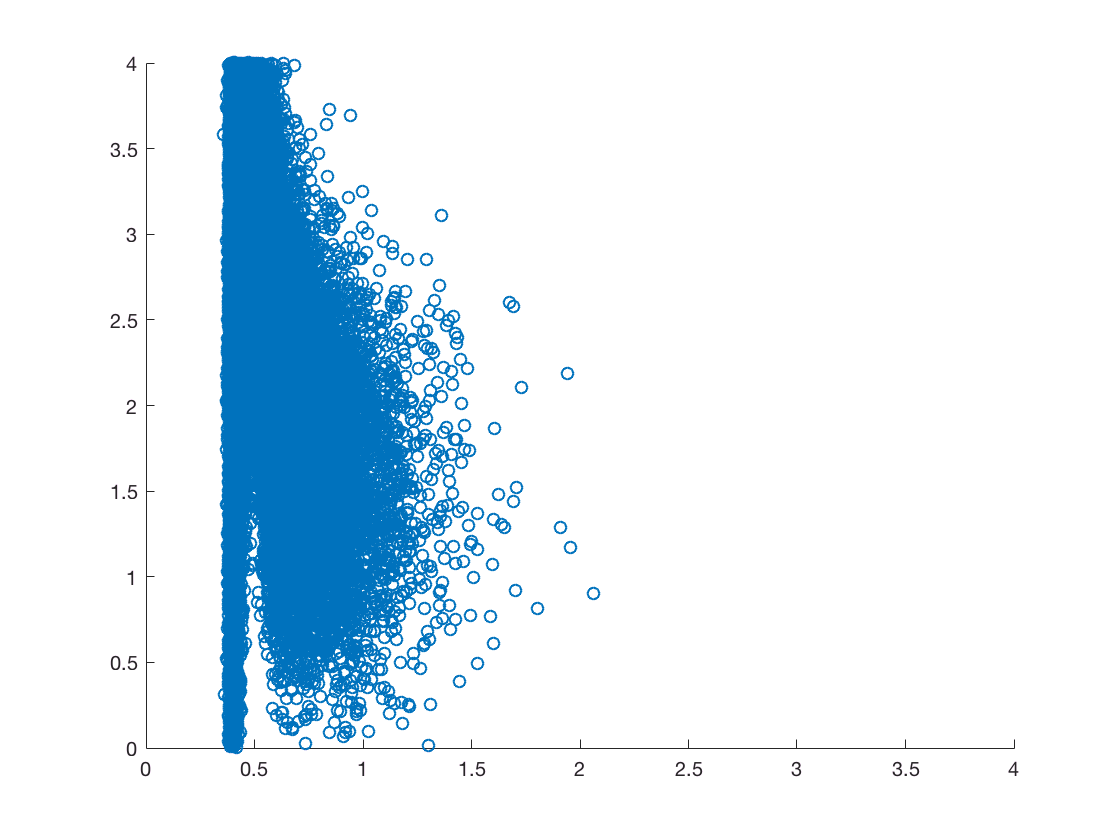

scatter(Ptlist,Ktlist);
xlim([0,4]);ylim([0,4]);

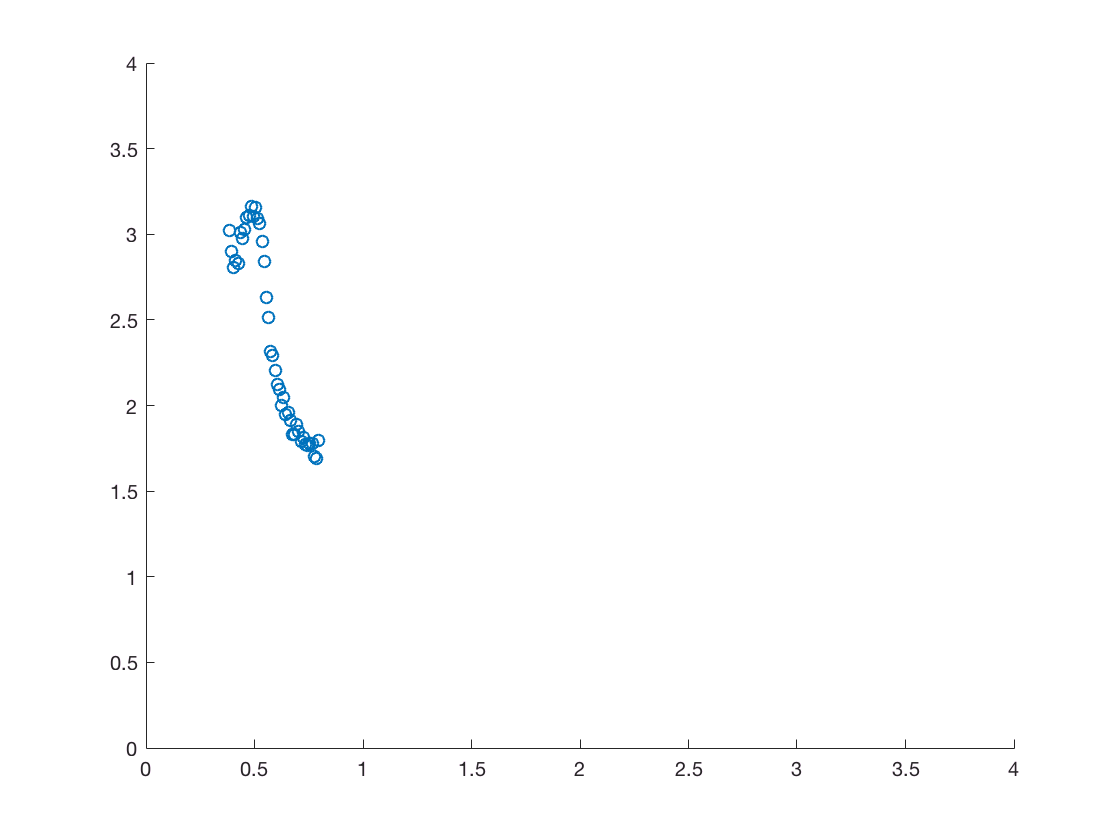

PTGrid=0:0.01:1.2;
[PtB,KtB]=BinGrid(Ptlist,Ktlist,PTGrid,200);
scatter(PtB,KtB)
xlim([0,4]);ylim([0,4])